% Link lengths
l1 = 3;
l2 = 3;
x_start = -pi/2

x_start = -1.5708

y_start = -4

y_start = -4


% Body dimensions
width = 5;
height = 2;
x_vertice = [0, width, 0, width]

x_vertice =      0     5     0     5


y_vertice = [0, height, height, 0]

y_vertice =      0     2     2     0



% Plot setup
figure;
axis equal;
grid on;
xlim([-5, 5 + width]);
ylim([-5, 5 + height]);
title('Task - 3');
hold on; 

% Four arms (quadruped)
X1 = [0, 0, 0, 0]

X1 =      0     0     0     0


Y1 = [0, 0, 0, 0]

Y1 =      0     0     0     0


X2 = [0, 0, 0, 0]

X2 =      0     0     0     0


Y2 = [0, 0, 0, 0]

Y2 =      0     0     0     0


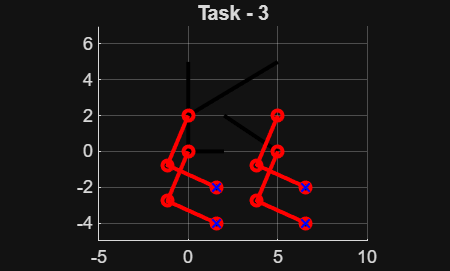


% Initialize arm position

for i = 1:4

    t = 0;
    x = x_start + t;
    y = y_start + 2 * sin(t);
    
    % Inverse Kinematics
    d = (x^2 + y^2 - l1^2 - l2^2) / (2 * l1 * l2);
    t2 = acos(d);
    k1 = l1 + l2 * cos(t2);
    k2 = l2 * sin(t2);
    t1 = atan2(y, x) - atan2(k2, k1);
    
    % Forward Kinematics
    x1 = l1 * cos(t1) + x_vertice(i);
    y1 = l1 * sin(t1) + y_vertice(i); 
    x2 = x1 + l2 * cos(t1 + t2);
    y2 = y1 + l2 * sin(t1 + t2);
    
   % Store the positions for each arm
    X1(i) = x1;
    Y1(i) = y1;
    X2(i) = x2;
    Y2(i) = y2;
end

% Main motion

for j = 1:4

    t_vals = linspace(0, pi, 100);
            
    for t = t_vals
        
        x = x_start + t;
        y = y_start + sin(t);

        % Body
        plot([0; 0], [width; 0], 'k-', 'LineWidth', 2);
        plot([width; 0], [width; height], 'k-', 'LineWidth', 2);
        plot([width; height], [0; height], 'k-', 'LineWidth', 2);
        plot([0; height], [0; 0], 'k-', 'LineWidth', 2);

        % Remove tracing arms
        delete(findobj(gca, 'Type', 'line', '-and', 'Color', 'r'));
        delete(findobj(gca, 'Type', 'line', '-and', 'Marker', 'x'));

        for i = 1:4

            if i == j

                % Inverse Kinematics
                d = (x^2 + y^2 - l1^2 - l2^2) / (2 * l1 * l2);
                t2 = acos(d);
                k1 = l1 + l2 * cos(t2);
                k2 = l2 * sin(t2);
                t1 = atan2(y, x) - atan2(k2, k1);
            
                % Forward Kinematics
                x1 = l1 * cos(t1) + x_vertice(i);
                y1 = l1 * sin(t1) + y_vertice(i); 
                x2 = x1 + l2 * cos(t1 + t2);
                y2 = y1 + l2 * sin(t1 + t2);

                % Update info
                X1(i) = x1;
                Y1(i) = y1;
                X2(i) = x2;
                Y2(i) = y2;

            else

                % Update for next arm
                x1 = X1(i);
                y1 = Y1(i);
                x2 = X2(i);
                y2 = Y2(i);

            end

            plot([x_vertice(i), x1, x2], [y_vertice(i), y1, y2], 'ro-', 'LineWidth', 2, 'MarkerSize', 5);
            plot(x2, y2, 'bx', 'MarkerSize', 6, 'LineWidth', 1);

        end

        drawnow;
        pause(0.01);

    end
end